# Performance of  Different Loop Orderings

This Live Script helps you view the performance of implementations of MMM with different loop orderings 

To gather the performance data, implement

    Gemm_IJP.c   (Already given.  Execute 'make IJP' in the terminal window.)

    Gemm_JIP.c   (Implement.       Execute 'make JIP' in the terminal window.)

    Gemm_IPJ.c   (Implement.       Execute 'make IPJ' in the terminal window.)

    Gemm_PIJ.c   (Implement.       Execute 'make PIJ' in the terminal window.)

    Gemm_JPI.c   (Implement.       Execute 'make JPI' in the terminal window.)

    Gemm_PJI.c   (Implement.       Execute 'make PJI' in the terminal window.)

To make it easy to add to the graph incrementally as you implement these different routines, as you add new implementations, change the 'NO' to a 'YES'.  If the refence is to be plotted, then the top of the graph is also adjusted to the theoretical peak performance.

plot_ref = 'NO';     % indicate if reference is to be ...  Until further notice, 
                     % leave this as 'NO'
plot_IJP = 'YES';     % indicate if IJP is to be plotted
plot_JIP = 'NO';     % indicate if JIP is to be plotted
plot_IPJ = 'NO';     % indicate if IPJ is to be plotted
plot_PIJ = 'NO';     % indicate if PIJ is to be plotted
plot_JPI = 'NO';     % indicate if JPI is to be plotted
plot_PJI = 'NO';     % indicate if JPI is to be plotted

When completed, these creates output files 'output_<version>.m' with timing data.  This Life Script then creates graphs from that timing data.

## Load data, check accuracy, and plot timing data

turbo_clock_rate = 2.6;
flops_per_cycle = 16;
peak_gflops = 2.6 * 16;

% Create figure
figure2 = figure('Name','Figure2');

% Create axes
axes2 = axes('Parent',figure2);
hold(axes2,'on');

if strcmp( plot_IJP, 'YES' )
    % Load data for IJP
    output_IJP
    
    if strcmp( plot_ref, 'YES' )
        % Plot time data for reference 
        plot( data(:,1), data(:,3), ...
              'MarkerSize', 8, 'LineWidth', 2, ...
              'DisplayName', 'reference', 'Color', [0 0 0] );
    end
      
    % Check accuracy
    if max( abs( data( :, 6 ) ) ) > 1.0e-10
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for IJP                
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 2, ...
          'DisplayName', 'IJP', 'Marker', 'o', ...
          'LineStyle', '-.', 'Color', [0 0 1] );
end

It appears all is fine


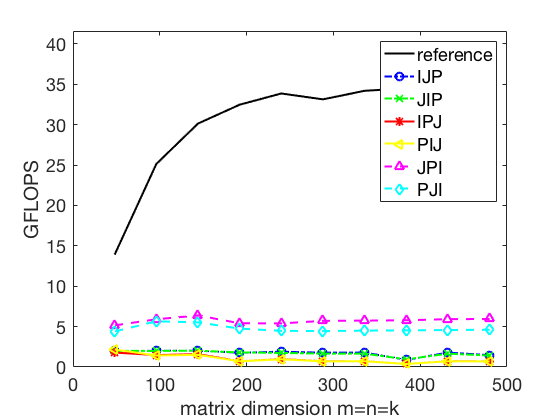


if strcmp( plot_JIP, 'YES' )
    % Load data for JIP
    output_JIP
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for JIP                
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 2, ...
          'DisplayName', 'JIP', 'Marker', 'x', ...
          'LineStyle', '-.', 'Color', [0 1 0] );
end

if strcmp( plot_IPJ, 'YES' )
    % Load data for IPJ
    output_IPJ
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for IPJ                
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 2, ...
          'DisplayName', 'IPJ', 'Marker', '*', ...
          'LineStyle', '-', 'Color', [1 0 0] );
end

if strcmp( plot_PIJ, 'YES' )
    % Load data for PIJ
    output_PIJ
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for PIJ                
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 2, ...
          'DisplayName', 'PIJ', 'Marker', '<', ...
          'LineStyle', '-', 'Color', [1 1 0] );
end

if strcmp( plot_JPI, 'YES' )
    % Load data for JPI
    output_JPI
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for JPI                
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 2, ...
          'DisplayName', 'JPI', 'Marker', '^', ...
          'LineStyle', '--', 'Color', [1 0 1] );
end

if strcmp( plot_PJI, 'YES' )
    % Load data for PJI
    output_PJI
    
    % Check accuracy
    if ( max( abs( data( :, 6 ) ) ) > 1.0e-10 )
        disp( 'Hmmm, better check if there is an accuracy problem' );
    else
        disp( 'It appears all is fine' );
    end
             
    % Plot time data for PJJ                
    plot( data(:,1), data(:,5), ...
          'MarkerSize', 8, 'LineWidth', 2, ...
          'DisplayName', 'PJI', 'Marker', 'diamond', ...
          'LineStyle', '--', 'Color', [0 1 1] );
end

% Create ylabel
ylabel( 'GFLOPS', 'FontName', 'Helvetica Neue' );

% Create xlabel
xlabel( 'matrix dimension m=n=k', 'FontName', 'Helvetica Neue' );

box(axes2,'on');
% Set the remaining axes properties
set(axes2,'FontName','Helvetica Neue','FontSize',18);

% Create legend
legend2 = legend(axes2,'show');

set(legend2,'Location','northeast','FontSize',18);

if strcmp( plot_ref, 'YES' )
    % Adjust the x-axis and y-axis range to start at 0
    v = axis;     % extract the current ranges
    axis( [ 0 v(2) 0 peak_gflops ] )  % start the x axis and y axis at zero and
                                  % scale the y axis so the top of the graph represents
                                  % theoretical peak performance.
else
    % Adjust the x-axis and y-axis range to start at 0
    v = axis;     % extract the current ranges
    axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero and
                                  % scale the y axis so the top of the graph represents
                                  % theoretical peak performance.
end

## Conclusion

By reordering the loops of the we can improve the peformance of the GEMM implementation. Can you reason through why some loop orderings perform better than the others?